L1=0.0005; %side length
L2=0.05

L2 = 0.0500

M=2500; %number of samples
dx1=L1/M; %src sample interval
x1=-L1/2:dx1:L1/2-dx1; %src coords
y1=x1;
dx2=L2/M;
% x2=-L2/2:dx2:L2/2-dx1; %src coords
% y2=x2;
x2=x1

x2 = 	1.0e+-3 *

   -0.2500   -0.2498   -0.2496   -0.2494   -0.2492   -0.2490   -0.2488   -0.2486   -0.2484   -0.2482   -0.2480   -0.2478   -0.2476   -0.2474   -0.2472   -0.2470   -0.2468   -0.2466   -0.2464   -0.2462   -0.2460   -0.2458   -0.2456   -0.2454   -0.2452   -0.2450   -0.2448   -0.2446   -0.2444   -0.2442   -0.2440   -0.2438   -0.2436   -0.2434   -0.2432   -0.2430   -0.2428   -0.2426   -0.2424   -0.2422   -0.2420   -0.2418   -0.2416   -0.2414   -0.2412   -0.2410   -0.2408   -0.2406   -0.2404   -0.2402


y2=y1

y2 = 	1.0e+-3 *

   -0.2500   -0.2498   -0.2496   -0.2494   -0.2492   -0.2490   -0.2488   -0.2486   -0.2484   -0.2482   -0.2480   -0.2478   -0.2476   -0.2474   -0.2472   -0.2470   -0.2468   -0.2466   -0.2464   -0.2462   -0.2460   -0.2458   -0.2456   -0.2454   -0.2452   -0.2450   -0.2448   -0.2446   -0.2444   -0.2442   -0.2440   -0.2438   -0.2436   -0.2434   -0.2432   -0.2430   -0.2428   -0.2426   -0.2424   -0.2422   -0.2420   -0.2418   -0.2416   -0.2414   -0.2412   -0.2410   -0.2408   -0.2406   -0.2404   -0.2402


lambda=0.5*10^-6; %wavelength
k=2*pi/lambda; %wavenumber
w=0.051; %source half width (m)
z=2000;

%parameters for HG00 input signals
w_in = 1e-5;        %width of HG00 signal
d = 2e-5;           %distance between centers of neighbour gaussian beams
f = 0.25;           %focus length of lens
r = 0.0125          %radius of lens

r = 0.0125

P=circle_window(x1,y1,r); %window for lens.

%generate two HG00 input signals

[X1,Y1]=meshgrid(x1,y1);

uin =  zeros(length(X1),length(Y1));
for i = -1:1
    for j = -1:1
        xc = d*i;
        yc = d*j;
        uin = uin +  exp(-((X1-xc).^2 + (Y1-yc).^2)/(w_in^2));
    end
end

I1=abs(uin.^2); %src irradiance


%Plot input signal 

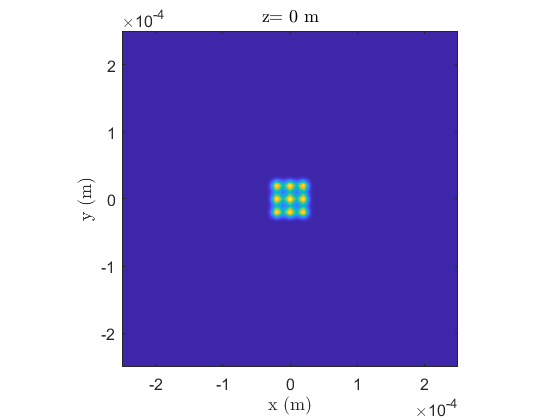

figure(1)
imagesc(x1,y1,I1);
axis square; axis xy;
xlabel('x (m)'); ylabel('y (m)');
title('z= 0 m')

uout=propTF(uin,L1,lambda,z); %propagation
uout = uout.*P;
uout=focus(uout,L1,lambda,f); %phase screen for first lens

% uout = prop2step(uout,L1,L2,lambda,f);
I2=abs(uout.^2); %obs irrad


%Plot output signal

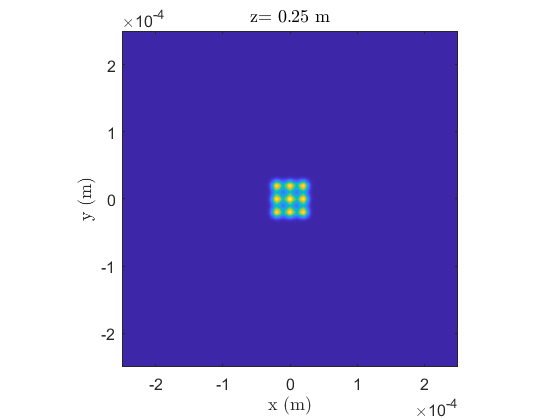

figure(2) %display obs irrad
imagesc(x2,y2,I2);%stretch image contrast
axis square; axis xy;
xlabel('x (m)'); ylabel('y (m)');
title(['z= ',num2str(f),' m']);